## Calculations

This is cleaned up calculations, to be documented, for determining the control system for our quadcopter.

Declare our symbolics

syms x1 x2 x3 phi theta psi v1 v2 v3 omega1 omega2 omega3 
syms u1 u2 u3 u4
syms g m l sigma c1 c2 c3 r1 r2 r3 e1 e2 e3 Ix Iy Iz

Build our system for our $\dot{z}$.

z = [x1; x2; x3; phi; theta; psi; v1; v2; v3; omega1; omega2; omega3;]

$$z = \left(\begin{array}{c} x_{1}\\ x_{2}\\ x_{3}\\ \varphi \\ \theta \\ \psi \\ v_{1}\\ v_{2}\\ v_{3}\\ \omega_{1}\\ \omega_{2}\\ \omega_{3} \end{array}\right)$$

u = [u1; u2; u3; u4;]

$$u = \left(\begin{array}{c} u_{1}\\ u_{2}\\ u_{3}\\ u_{4} \end{array}\right)$$


T_inv=[
        1 sin(phi)*tan(theta) cos(phi)*tan(theta);
        0 cos(phi) -sin(phi);
        0 sin(phi)/cos(theta) cos(phi)/cos(theta)
       ];

R_ce = [
            cos(theta)*cos(psi)         sin(phi)*sin(theta)*cos(psi)-cos(phi)*sin(psi)      sin(phi)*sin(psi)+cos(phi)*sin(theta)*cos(psi);
            cos(theta)*sin(psi)         cos(phi)*cos(psi)+sin(phi)*sin(theta)*sin(psi)      cos(phi)*sin(theta)*sin(psi)-sin(phi)*cos(psi);
            -sin(theta)                 sin(phi)*cos(theta)                                 cos(phi)*cos(theta);
       ];

e1=[1; 0; 0];
e2=[0; 1; 0];
e3=[0; 0; 1];

c1=[1; 0; 0];
c2=[0; 1; 0];
c3=[0; 0; 1];

n=[0; 0; 0];
r=[0; 0; 0];

I=[Ix 0 0;
    0 Iy 0;
    0 0 Iz];

xdot = [v1; v2; v3;]

$$xdot = \left(\begin{array}{c} v_{1}\\ v_{2}\\ v_{3} \end{array}\right)$$

alphadot = simplify(T_inv * [omega1; omega2; omega3;])

$$alphadot = \left(\begin{array}{c} \omega_{1}+\omega_{3}\,\cos\left(\varphi \right)\,\tan\left(\theta \right)+\omega_{2}\,\sin\left(\varphi \right)\,\tan\left(\theta \right)\\ \omega_{2}\,\cos\left(\varphi \right)-\omega_{3}\,\sin\left(\varphi \right)\\ \frac{\omega_{3}\,\cos\left(\varphi \right)+\omega_{2}\,\sin\left(\varphi \right)}{\cos\left(\theta \right)} \end{array}\right)$$

vdot=simplify(-g*e3+1/m*(R_ce*(u1+u2+u3+u4)*c3+1/m*R_ce*r))

$$vdot = \left(\begin{array}{c} \frac{\left(\sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\right)\,\left(u_{1}+u_{2}+u_{3}+u_{4}\right)}{m}\\ -\frac{\left(\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\right)\,\left(u_{1}+u_{2}+u_{3}+u_{4}\right)}{m}\\ \frac{\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\left(u_{1}+u_{2}+u_{3}+u_{4}\right)}{m}-g \end{array}\right)$$

omegadot=simplify(inv(I)*((u2-u4)*l*c1+(u3-u1)*l*c2+(u1-u2+u3-u4)*sigma*c3+n-cross([omega1; omega2; omega3;],I*[omega1; omega2; omega3;])))

$$omegadot = \left(\begin{array}{c} \frac{l\,\left(u_{2}-u_{4}\right)+\mathrm{Iy}\,\omega_{2}\,\omega_{3}-\mathrm{Iz}\,\omega_{2}\,\omega_{3}}{\mathrm{Ix}}\\ -\frac{l\,\left(u_{1}-u_{3}\right)+\mathrm{Ix}\,\omega_{1}\,\omega_{3}-\mathrm{Iz}\,\omega_{1}\,\omega_{3}}{\mathrm{Iy}}\\ \frac{\sigma \,\left(u_{1}-u_{2}+u_{3}-u_{4}\right)+\mathrm{Ix}\,\omega_{1}\,\omega_{2}-\mathrm{Iy}\,\omega_{1}\,\omega_{2}}{\mathrm{Iz}} \end{array}\right)$$


zdot = [xdot; alphadot; vdot; omegadot;]

$$zdot = \left(\begin{array}{c} v_{1}\\ v_{2}\\ v_{3}\\ \omega_{1}+\omega_{3}\,\cos\left(\varphi \right)\,\tan\left(\theta \right)+\omega_{2}\,\sin\left(\varphi \right)\,\tan\left(\theta \right)\\ \omega_{2}\,\cos\left(\varphi \right)-\omega_{3}\,\sin\left(\varphi \right)\\ \frac{\omega_{3}\,\cos\left(\varphi \right)+\omega_{2}\,\sin\left(\varphi \right)}{\cos\left(\theta \right)}\\ \frac{\left(\sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\right)\,\left(u_{1}+u_{2}+u_{3}+u_{4}\right)}{m}\\ -\frac{\left(\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\right)\,\left(u_{1}+u_{2}+u_{3}+u_{4}\right)}{m}\\ \frac{\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\left(u_{1}+u_{2}+u_{3}+u_{4}\right)}{m}-g\\ \frac{l\,\left(u_{2}-u_{4}\right)+\mathrm{Iy}\,\omega_{2}\,\omega_{3}-\mathrm{Iz}\,\omega_{2}\,\omega_{3}}{\mathrm{Ix}}\\ -\frac{l\,\left(u_{1}-u_{3}\right)+\mathrm{Ix}\,\omega_{1}\,\omega_{3}-\mathrm{Iz}\,\omega_{1}\,\omega_{3}}{\mathrm{Iy}}\\ \frac{\sigma \,\left(u_{1}-u_{2}+u_{3}-u_{4}\right)+\mathrm{Ix}\,\omega_{1}\,\omega_{2}-\mathrm{Iy}\,\omega_{1}\,\omega_{2}}{\mathrm{Iz}} \end{array}\right)$$

From our calculated $\dot{z}$, find A and B via the Jacobian. We are also assuming that we are near a hover position to linearize the equation - essentially $\phi$, $\theta$, and $\psi$ are 0, and $u_1 +u_2 +u_3 +u_4 =\textrm{mg}$, thus $u_i =\frac{\textrm{mg}}{4}$.

global A B

A = jacobian(zdot, z)

B = jacobian(zdot, u)

$$B = \begin{array}{l} \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ \sigma_{2} & \sigma_{2} & \sigma_{2} & \sigma_{2}\\ \sigma_{1} & \sigma_{1} & \sigma_{1} & \sigma_{1}\\ \sigma_{3} & \sigma_{3} & \sigma_{3} & \sigma_{3}\\ 0 & \frac{l}{\mathrm{Ix}} & 0 & -\frac{l}{\mathrm{Ix}}\\ -\frac{l}{\mathrm{Iy}} & 0 & \frac{l}{\mathrm{Iy}} & 0\\ \frac{\sigma }{\mathrm{Iz}} & -\frac{\sigma }{\mathrm{Iz}} & \frac{\sigma }{\mathrm{Iz}} & -\frac{\sigma }{\mathrm{Iz}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)}{m}\\ \sigma_{2}=\frac{\sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)}{m}\\ \sigma_{3}=\frac{\cos\left(\varphi \right)\,\cos\left(\theta \right)}{m} \end{array}$$


phi=0;
theta=0;
psi=0;
v1=0;
v2=0;
v3=0;
omega1=0;
omega2=0;
omega3=0;
u1=m*g/4;
u2=m*g/4;
u3=m*g/4;
u4=m*g/4;

A = subs(A)

$$A = \left(\begin{array}{cccccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & g & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & -g & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

B = subs(B)

$$B = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ \frac{1}{m} & \frac{1}{m} & \frac{1}{m} & \frac{1}{m}\\ 0 & \frac{l}{\mathrm{Ix}} & 0 & -\frac{l}{\mathrm{Ix}}\\ -\frac{l}{\mathrm{Iy}} & 0 & \frac{l}{\mathrm{Iy}} & 0\\ \frac{\sigma }{\mathrm{Iz}} & -\frac{\sigma }{\mathrm{Iz}} & \frac{\sigma }{\mathrm{Iz}} & -\frac{\sigma }{\mathrm{Iz}} \end{array}\right)$$

Now we check for the controllability of our control matrix.

C = [B A*B A^2*B A^3*B A^4*B A^5*B A^6*B A^7*B A^8*B A^9*B A^10*B A^11*B];
rank(C)

ans = 12

We see that the rank of the C matrix is equivalent to our size of z, so we have a fully controllable system.

interceptor = create_quadcopter([0 0 0], [0 0 0], [0 0 0], [0 0 0], 0.5, .4, .08, 'blue', 'green', 'blue')

interceptor = struct with fields:
                mass: 0.5000
          arm_length: 0.4000
           prop_size: 0.0800
          arms_color: 'blue'
         props_color: 'green'
    trajectory_color: 'blue'
                 xyz: [0 0 0]
            rotation: [0 0 0]
            velocity: [0 0 0]
               omega: [0 0 0]



[a, b] = get_quadcopter_A_and_B(interceptor)

a =          0         0         0         0         0         0    1.0000         0         0         0         0         0
         0         0         0         0         0         0         0    1.0000         0         0         0         0
         0         0         0         0         0         0         0         0    1.0000         0         0         0
         0         0         0         0         0         0         0         0         0    1.0000         0         0
         0         0         0         0         0         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0         0         0         0         0         0    1.0000
         0         0         0         0    9.8000         0         0         0         0         0         0         0
         0         0         0   -9.8000         0         0         0         0         0         0         0         0
         0         0        

b =          0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
    2.0000    2.0000    2.0000    2.0000
         0    0.3226         0   -0.3226


Once we have our A and B, we assign to the quacopter a Q and R for our desired performance.

interceptor.Q = eye(12);
interceptor.R = eye(4);

...and finally, we have MATLAB calculate the resulting K for our given system via the lqr function.

interceptor.K = lqr(a, b, interceptor.Q, interceptor.R);
interceptor.K

ans =    -0.7071   -0.0000    0.5000    0.0000  -13.2298    0.5000   -1.5521   -0.0000    0.6124    0.0000   -6.4430    1.8303
   -0.0000   -0.7071    0.5000   13.2298    0.0000   -0.5000    0.0000   -1.5521    0.6124    6.4430    0.0000   -1.8303
    0.7071    0.0000    0.5000   -0.0000   13.2298    0.5000    1.5521    0.0000    0.6124   -0.0000    6.4430    1.8303
    0.0000    0.7071    0.5000  -13.2298   -0.0000   -0.5000   -0.0000    1.5521    0.6124   -6.4430   -0.0000   -1.8303


Now that we have our K for our given interceptor model, we can generate a trajectory via solving the ODE for the given system of $\dot{e}$ utilizing our calculated K. Here we will assign our quadcopter a given starting stationary position and end at another stationary position.

interceptor.xyz = [1 1 1];
e0 = [2;3;5;0;0;pi;0;0;0;0;0;0];
tspan = 0:0.1:5;
[t,e] = ode45(@(t,e) (a-b*interceptor.K)*e,tspan,e0)

t =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


e =     2.0000    3.0000    5.0000         0         0    3.1416         0         0         0         0         0         0
    2.0000    2.9999    4.9148    0.0059   -0.0040    3.1391   -0.0013   -0.0020   -1.5707    0.1103   -0.0736   -0.0492
    1.9995    2.9992    4.7077    0.0205   -0.0137    3.1319   -0.0096   -0.0145   -2.4836    0.1749   -0.1166   -0.0955
    1.9977    2.9965    4.4324    0.0397   -0.0265    3.1201   -0.0292   -0.0438   -2.9647    0.2037   -0.1358   -0.1390
    1.9932    2.9898    4.1240    0.0604   -0.0402    3.1041   -0.0619   -0.0928   -3.1659    0.2051   -0.1367   -0.1798
    1.9848    2.9773    3.8052    0.0801   -0.0534    3.0842   -0.1079   -0.1618   -3.1897    0.1866   -0.1244   -0.2179
    1.9712    2.9569    3.4898    0.0972   -0.0648    3.0606   -0.1660   -0.2489   -3.1032    0.1544   -0.1029   -0.2535
    1.9513    2.9270    3.1867    0.1107   -0.0738    3.0336   -0.2341   -0.3512   -2.9530    0.1137   -0.0758   -0.2867
    1.9242    2.8863    2.90

Now, given our error over time, we can utilize that to blah blah

z_desired = [3; 3; 3; 0; 0; 0; 0; 0; 0; 0; 0; 0;]

z_desired =      3
     3
     3
     0
     0
     0
     0
     0
     0
     0


states = calculate_trajectory_to_state(interceptor, z_desired, tspan);

## Drawing our quadcopter in motion

Here, we are testing some drawing tools to draw our quadcopter in motion.

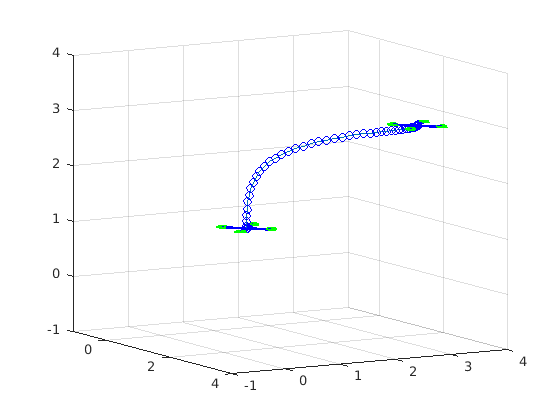

figure
hold on
view(60,10)
grid on
xlim([-1, 4])
ylim([-1,4])
zlim([-1,4])
hold on;

plot_quadcopter_trajectory(states);

hold off

## TODO :

Hover with a set force in a consistent direction.

## Intercepting Another Drone

Now that we have trajectory drawing for a set trajectory, and a quadcopter with a control system, let's see if we can code a system for our interception. We'll need to rework the control logic to swap the desired position of our interceptor drone for the changing position of our target drone. We'll have to also detect where, if at all, the interceptor drone is within a certain magnitude distance of the target drone so as to represent "capture".

To do this, we will generate the trajectory over a set amount of time for each, and then compare the trajectories at each timestamp.

Please see intercept_drone function below.

tspan = 0:0.1:5;
syms t
target_trajectory = [sin(t)+1; cos(t)+1; ones(1,length(t))*2;];
target_xyz = transpose(double(subs(target_trajectory, "t", 0)))

target_xyz =      1     2     2


target = create_quadcopter(target_xyz, [0 0 0 ], [0 0 0], [0 0 0], 0.25, .2, .04, 'red', 'yellow', 'red')

target = struct with fields:
                mass: 0.2500
          arm_length: 0.2000
           prop_size: 0.0400
          arms_color: 'red'
         props_color: 'yellow'
    trajectory_color: 'red'
                 xyz: [1 2 2]
            rotation: [0 0 0]
            velocity: [0 0 0]
               omega: [0 0 0]


interceptor.xyz = [5 5 0];
[interceptor_states, target_states, time_intercept] = intercept_drone(interceptor, target, target_trajectory, tspan)

t =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


e =    -4.0000   -3.0000    2.0000         0         0         0         0         0         0         0         0         0
   -3.9999   -2.9999    1.9659   -0.0059    0.0079   -0.0000    0.0027    0.0020   -0.6283   -0.1104    0.1469   -0.0000
   -3.9990   -2.9992    1.8831   -0.0206    0.0273   -0.0000    0.0193    0.0145   -0.9934   -0.1750    0.2326   -0.0000
   -3.9953   -2.9965    1.7730   -0.0398    0.0528   -0.0000    0.0582    0.0438   -1.1858   -0.2039    0.2702   -0.0000
   -3.9865   -2.9898    1.6496   -0.0604    0.0802   -0.0000    0.1234    0.0929   -1.2663   -0.2057    0.2715   -0.0000
   -3.9698   -2.9772    1.5220   -0.0802    0.1063   -0.0000    0.2149    0.1619   -1.2758   -0.1875    0.2466   -0.0000
   -3.9427   -2.9568    1.3959   -0.0975    0.1289   -0.0000    0.3305    0.2493   -1.2413   -0.1556    0.2038   -0.0000
   -3.9030   -2.9269    1.2746   -0.1110    0.1467   -0.0000    0.4660    0.3518   -1.1811   -0.1151    0.1500   -0.0000
   -3.8490   -2.8861    1.16

interceptor_states = 1×51 struct array with fields:
    mass
    arm_length
    prop_size
    arms_color
    props_color
    trajectory_color
    xyz
    rotation
    velocity
    omega
    Q
    R
    K
    A
    B


target_states = 1×51 struct array with fields:
    mass
    arm_length
    prop_size
    arms_color
    props_color
    trajectory_color
    xyz
    rotation
    velocity
    omega


time_intercept = -1

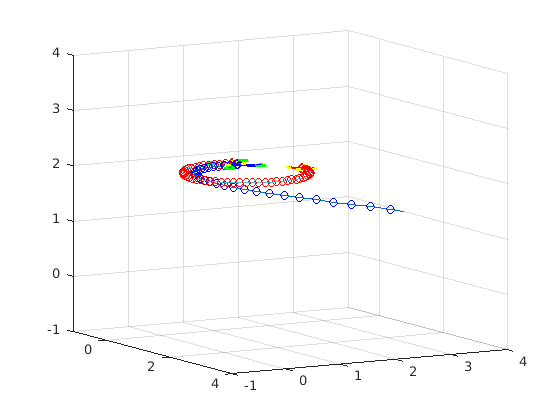


figure
hold on
view(60,10)
grid on
xlim([-1, 4])
ylim([-1,4])
zlim([-1,4])
hold on;

plot_quadcopter_trajectory(interceptor_states);
plot_quadcopter_trajectory(target_states);

hold off

## Intercept Functions

These are functions that aid in the process of intercepting and capturing a target drone.

### intercept_drone

intercept_drone accepts a given interceptor drone, a given target drone, the target drone's path, and a given timespan. It will then return the state list for each quadcopter, and a time that they became close enough to be considered "intercepting". Note that if no intercept exists, then the time_intercept result will be -1.

function [interceptor_states, target_states, time_intercept] = intercept_drone(interceptor, target, target_trajectory, tspan)
    global last_known_position
    time_intercept = -1;
    interceptor_states = [];
    target_states = [];
    
    interceptor = prepare_quadcopter_for_control_system(interceptor);
    
    last_known_position = target.xyz;
    
    e_xyz = transpose(target.xyz - interceptor.xyz);
    e_rotation = transpose(target.rotation - interceptor.rotation);
    e_v = transpose(target.velocity - interceptor.velocity);
    e_omega = transpose(target.omega - interceptor.omega);
    e0 = [e_xyz; e_rotation; e_v; e_omega;];
    
    [t,e]=ode45(@(t,e) intercept_control_ode(interceptor.A,...
        interceptor.B, interceptor.K, target_trajectory, t, e), tspan, e0);
    
    % Now that we've got our error over a given time, let's apply it to
    % our quadcopter by generating a series of quadcopter states.
    for i = 1:length(e)
        error = transpose(e(i,:));
        z_desired = double(subs(target_trajectory, "t", tspan(i)));
        zi = [z_desired - error(1:3); zeros(9, 1)];
        quad_new = interceptor;
        quad_new.xyz = transpose(zi(1:3));
        quad_new.rotation = transpose(zi(4:6));
        quad_new.velocity = transpose(zi(7:9));
        quad_new.omega = transpose(zi(10:12));
        interceptor_states = [interceptor_states quad_new];
        quad_target_new = target;
        target.xyz = transpose(z_desired);
        target_states = [target_states target];
    end
end

### intercept_control_ode

We need to do a bunch of variable reassignment during the intercept ODE. As a result, it's easier to just handle it as a function rather than an anonymous function.

function edot = intercept_control_ode(A, B, K, target_trajectory, t, e)
    global last_known_position;
    
    % First we calculate position of the interceptor, which is the last
    % known position modified by the error.
    current_interceptor_xyz = transpose(transpose(last_known_position) - e(1:3,1));
    
    % Then we need to calculate our new error. We first calculate where the
    % target is at the current time t, and then find the difference between
    % the position of our interceptor and our target.
    target_new_xyz = double(subs(target_trajectory, "t", t));
    % We also must update the last_known_position of the target
    last_known_position = transpose(target_new_xyz);

    error = [target_new_xyz-transpose(current_interceptor_xyz); e(4:12)];
    
    % Finally we calculate the change in error, edot, that we wish to see
    % with our control function.
    edot = (A-B*K)*error;
end

## Control Functions

### calculate_trajectory_to_state

calculate_trajectory_to_state takes a given quadcopter, a desired state z, and a timespan. It will then utilize its control system (or generate one if it has not done so already), and utilize that to create a trajectory consisting of a series of quadcopter states. It does this by solving the ODE for our system $\dot{e}$.

function quadcopter_states = calculate_trajectory_to_state(quadcopter, z, tspan)
    quadcopter_states = [];
    
    quadcopter = prepare_quadcopter_for_control_system(quadcopter);
    
    e_xyz = z(1:3) - transpose(quadcopter.xyz);
    e_rotation = z(4:6) - transpose(quadcopter.rotation);
    e_v = z(7:9) - transpose(quadcopter.velocity);
    e_omega = z(10:12) - transpose(quadcopter.omega);
    e0 = [e_xyz; e_rotation; e_v; e_omega;];
    
    [t,e]=ode45(@(t,e) (quadcopter.A-quadcopter.B*quadcopter.K)*e,tspan,e0);
    
    % Now that we've got our error over a given time, let's apply it to
    % our quadcopter by generating a series of quadcopter states.
    for i = 1:length(e)
%         error = e0 - transpose(e(i,:));
        error = transpose(e(i,:));
        zi = z - error;
        quad_new = quadcopter;
        quad_new.xyz = transpose(zi(1:3));
        quad_new.rotation = transpose(zi(4:6));
        quad_new.velocity = transpose(zi(7:9));
        quad_new.omega = transpose(zi(10:12));
        quadcopter_states = [quadcopter_states quad_new];
    end
end

### calculate_position

calculate_position accepts a given z and an error and returns the current position

### prepare_quadcopter_for_control_system

prepare_quadcopter_for_control_system accepts a quadcopter object and returns it. If the A, B, Q, R, or K were not already set on this quadcopter, it will generate defaults for all of them and assign it, returning a quadcopter with the settings configured.

function quadcopter = prepare_quadcopter_for_control_system(quadcopter)
    if ~isfield(quadcopter, 'A') | ~isfield(quadcopter, 'B')
        [a, b] = get_quadcopter_A_and_B(quadcopter);
        quadcopter.A = a;
        quadcopter.B = b;
    end
    
    if ~isfield(quadcopter, 'Q')
        quadcopter.Q = eye(12);
    end
    
    if ~isfield(quadcopter, 'R')
        quadcopter.R = eye(4);
    end
    
    if ~isfield(quadcopter, 'K')
        quadcopter.K = lqr(quadcopter.A, quadcopter.B, quadcopter.Q, quadcopter.R);
    end
end

### get_quadcopter_A_and_B

get_quadcopter_A_and_B takes a given quadcopter object, and returns the A and B numerical matrix for its control. It reaches for the global syms generated A and B for now.

function [a, b] = get_quadcopter_A_and_B(quadcopter)
    global A B
    syms m l Ix Iy Iz g
    a = subs(A, [m l Ix Iy Iz "sigma" g], [...
        quadcopter.mass quadcopter.arm_length ...
        1.24 1.24 1.24 0.1 9.8]);
    b = subs(B, [m l Ix Iy Iz "sigma" g], [...
        quadcopter.mass quadcopter.arm_length ...
        1.24 1.24 1.24 0.1 9.8]);
    a = double(a);
    b = double(b);
end

### trajectory_to_quadcopter_states

trajectory_to_quadcopter_states accepts a given 

function quadcopter_states = trajectory_to_quadcopter_states(quadcopter, xyz_trajectory)
    quadcopter_states = [];
    for t = 1:length(xyz_trajectory)
        tmp_quad = quadcopter;
        tmp_quad.xyz = transpose(xyz_trajectory(:,t));
        quadcopter_states = [quadcopter_states tmp_quad];
    end
end

## Quadcopter Functions

### create_quadcopter

create_quadcopter creates a quadcopter struct object for tracking stats abouts the quadcopter for easily handling. It also tracks the current xyz

function quadcopter = create_quadcopter(xyz, rotation, velocity, omega, mass, arm_length, prop_size, arms_color, props_color, trajectory_color)
    quadcopter = struct(...
        "mass", mass, "arm_length", arm_length, "prop_size", prop_size, ...
        "arms_color", arms_color, "props_color", props_color, ...
        "trajectory_color", trajectory_color, ...
        "xyz", xyz, "rotation", rotation, "velocity", velocity, "omega", omega);
end

### quadcopter_rotation

quadocopter_rotation will, given a quadcopter, return the roll pitch yaw rotation matrix for the current orientation.

function R = quadcopter_rotation(quadcopter)
    phi = quadcopter.rotation(1);
    theta = quadcopter.rotation(2);
    psi = quadcopter.rotation(3);
    R=[cos(theta)*cos(psi) sin(phi)*sin(theta)*cos(psi)-cos(phi)*sin(psi) sin(phi)*sin(psi)+cos(phi)*sin(theta)*cos(psi);
    cos(theta)*sin(psi) cos(phi)*cos(psi)+sin(phi)*sin(theta)*sin(psi) cos(phi)*sin(theta)*sin(psi)-sin(phi)*cos(psi);
    -sin(theta) sin(phi)*cos(theta) cos(phi)*cos(theta)];
end

### update_quadcopter

update_quadcopter takes a quadcopter and a $\dot{z}$ and returns a quadcopter with updated values

function quadcopter = update_quadcopter(quadcopter, zdot)
    delta_xyz = [zdot(1); zdot(2); zdot(3);];
    delta_rotation = [zdot(4); zdot(5); zdot(6);],
    quadcopter = move_quadcopter(quadcopter, delta_xyz, delta_rotation);
end

### move_quadcopter

move_quadcopter takes a quadcopter and a given delta xyz and delta rotation. These move the quadcopter the given delta from its current position/orientation to its resulting new one. Because MATLAB is pass by value, it returns a new quadcopter struct.

function quadcopter = move_quadcopter(quadcopter, delta_xyz, delta_rotation)
    quadcopter.xyz = quadcopter.xyz + delta_xyz;
    quadcopter.rotation = quadcopter.rotation + delta_rotation;
end

## Drawing Functions

### plot_quadcopter

plot_quadcopter will take a given a quadcopter struct object. From this object it will ascertain the XYZ center origin of a drone (center of mass), and given roll, pitch, yaw orientation (in radians). It assumes that a figure is already active to be drawing in.

It will return the resutling graphics handles for optional cleanup in case of animation. Color options that can be passed in are optional, in the event of desired variability in copter design.

function handles = plot_quadcopter(quadcopter)
    handles = [];

    center = quadcopter.xyz;
    r = quadcopter.prop_size;
    rotate = quadcopter_rotation(quadcopter);
    l = quadcopter.arm_length;
    
    z = [0;0;1];
    
    norm = transpose(r*z);
    
    %the base quad setup at zero
    LF0 = [l*cos(pi/4);l*sin(pi/4);0];
    LR0 = [l*cos(3*pi/4);l*sin(3*pi/4);0];
    RR0 = [l*cos(5*pi/4);l*sin(5*pi/4);0];
    RF0 = [l*cos(7*pi/4);l*sin(7*pi/4);0];
    
   %Quad rotated through R matrix
    LF = [center; [center+transpose(rotate*LF0)]];
    LR = [center; [center+transpose(rotate*LR0)]];
    RR = [center; [center+transpose(rotate*RR0)]];
    RF = [center; [center+transpose(rotate*RF0)]];
    
    %plotting
    handles = [plot3(center(1), center(2), center(3),"-bo", "LineWidth", 2, 'Color', quadcopter.arms_color)];
    handles = [handles; plot3(LF(:,1), LF(:,2),LF(:,3),"-", "LineWidth", 2, 'Color', quadcopter.arms_color)];
    handles = [handles; plot_circle_3d(LF(2,:), norm,r, quadcopter.props_color)];
    handles = [handles; plot3(LR(:,1), LR(:,2),LR(:,3),"-", "LineWidth", 2, 'Color', quadcopter.arms_color)];
    handles = [handles; plot_circle_3d(LR(2,:),norm,r, quadcopter.props_color)];
    handles = [handles; plot3(RR(:,1), RR(:,2),RR(:,3),"-", "LineWidth", 2, 'Color', quadcopter.arms_color)];
    handles = [handles; plot_circle_3d(RR(2,:), norm,r, quadcopter.props_color)];
    handles = [handles; plot3(RF(:,1), RF(:,2),RF(:,3),"-", "LineWidth", 2, 'Color', quadcopter.arms_color)];
    handles = [handles; plot_circle_3d(RF(2,:), norm,r, quadcopter.props_color)];

end

### plot_circle_3d

plot_circle_3d takes a circle center, its normal vector, and a radius. It then draws the resulting circle in 3d space at the correct orientation.

function h=plot_circle_3d(center,normal,radius, color)
    theta=0:0.01:2*pi;
    v=null(normal);
    points=repmat(center',1,size(theta,2))+radius*(v(:,1)*cos(theta)+v(:,2)*sin(theta));
    h=plot3(points(1,:),points(2,:),points(3,:),'-',  "LineWidth", 2, 'Color', color);
end

### plot_quadcopter_trajectory

plot_quadcopter_trajectory takes a an array of quadcopter structs, each representing a state of the quadcopter at a given point in time. From this, it will generate a list of XYZ center points denoting where the quadcopter is, a list of roll pitch yaw rotations. It plots the points of the trajectory as a dotted line of the quadcopter's specified trajectory color. It will plot the quadcopter at the beginning and end of the path.

function handles = plot_quadcopter_trajectory(quadcopter_states)
    % First plot the trajectory
    handles = [];
    xyzs = zeros(3, length(quadcopter_states));
    for i = 1:length(quadcopter_states)
        xyzs(:, i) = quadcopter_states(i).xyz;
    end
    plot3(xyzs(1,:), xyzs(2,:), xyzs(3,:), "-o", "MarkerSize", 6, "MarkerEdgeColor", quadcopter_states(1).trajectory_color);
    
    % Now plot the start and finish
    plot_quadcopter(quadcopter_states(1));
    plot_quadcopter(quadcopter_states(length(quadcopter_states)));
end